# ASE-4046 Exercise 6 Solutions

## Problem 1

***Part a***

Plot the options' costs. 

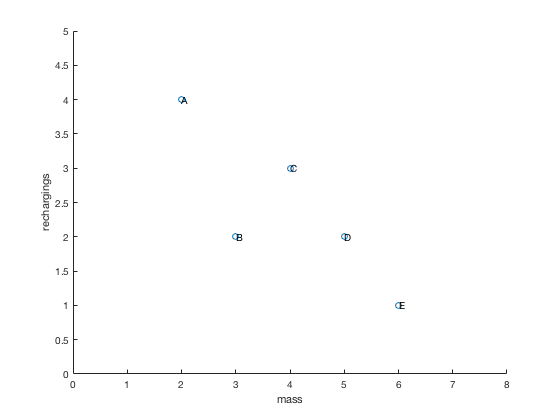

mass=[2 3 4 5 6];
rechargings=[4 2 3 2 1];
label='ABCDE';
plot(mass,rechargings,'o')
axis([0 8 0 5]), xlabel('mass'), ylabel('rechargings'), box off
hold on, for k=1:5,text(mass(k),rechargings(k),label(k)),end, hold off

A, B, and E are Pareto optimal, they are not dominated. C and D are not Pareto optimal: C is dominated (B is better in both criteria) and D is dominated (B is at least as good as D in both criteria, and has better weight.)   

D is weakly Pareto optimal:  there is no option that is better than D in both criteria. A, B, E are weakly Pareto optimal because they are Pareto optimal. 

***Part b***

The scalarised cost function's values are 

a=[1,1];
f=a(1)*mass+a(2)*rechargings

f =      6     5     7     7     7


Thus the best option (the one with the smallest weighted sum) is B. 

Redraw the figure:

clf % clear figure
plot(mass,rechargings,'o')
axis([0 8 0 5]), xlabel('mass'), ylabel('rechargings'), box off
hold on, for k=1:5,text(mass(k),rechargings(k),label(k)),end, hold off

Add the indifference curve, which is a straight line of slope -1 that goes through B: 

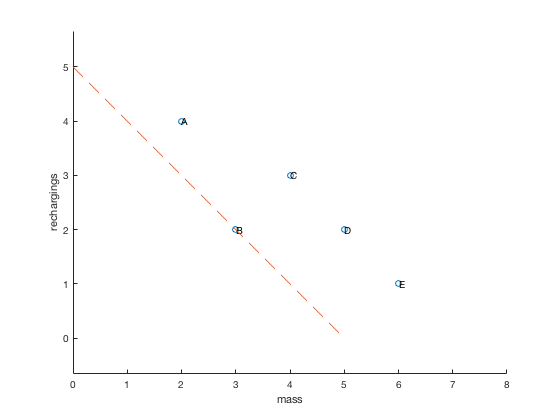

hold on, plot([0 5],[5 0],'--'), hold off, axis equal

***Part c***

Redraw the figure and plot the goal and the line search.

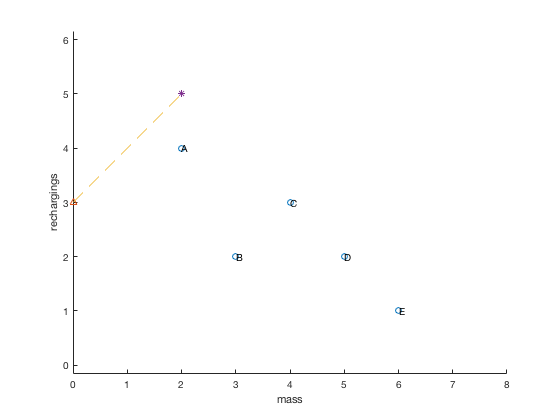

clf, plot(mass,rechargings,'o')
axis([0 8 0 5]), xlabel('mass'), ylabel('rechargings'), box off
hold on, for k=1:5,text(mass(k),rechargings(k),label(k)),end, hold off
hold on, plot(0,3,'^',[0 2],[3 5],'--',2,5,'*'), hold off, axis equal

The search is along a line of slope 1 that starts at the goal (0,3). The line search stops at  (2,5) because mass(A) =2 ≤ 2 and rechargings(A) = 4 ≤ 5. That is, the goal attainment inequality $f\leq f^\ast + \gamma \mathbf{1}$ is satisfied with attainable cost $f=(2,4)$ and $f^\ast + \gamma \mathbf{1}=(0,3)+2\cdot (1,1)=(2,5)$.  The goal attainment solution is option A with $\gamma=2$. Positive $\gamma$ means underattainment.

***Part d***

Redraw the figure and plot the goal and the line search.

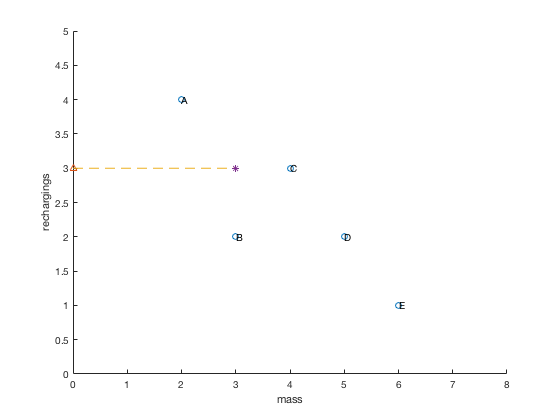

clf, plot(mass,rechargings,'o')
axis([0 8 0 5]), xlabel('mass'), ylabel('rechargings'), box off
hold on, for k=1:5,text(mass(k),rechargings(k),label(k)),end, hold off
hold on, plot(0,3,'^',[0 3],[3 3],'--',3,3,'*'), hold off

The search is along a line of slope 0 that starts at the goal (0,3) and stops at (3,3). The search stops here because mass(B) ≤ 3 and rechargings(B) ≤ 3.  The goal attainment solution is thus option B.

## Problem 2

***Part a***

The problem constants are

F=10; E=2e5; L=200; sigma=10; rho=0.0077;

The cost functions are

Mcoeff=rho*L*[2 sqrt(2)  sqrt(2) 1];
M=@(A) Mcoeff*A(:);
Delta=@(A) F*L/E*(2/A(1)+2*sqrt(2)/A(2)-2*sqrt(2)/A(3)+2/A(4));

The stress constraints can be written as lower and upper bounds on the bar areas:

lb=[1 sqrt(2) sqrt(2) 1]*F/sigma;
ub=[3 3 3 3]*F/sigma; 

The utopia costs are computed by solving the individual optimisation problems separately.

The mass minimisation can be computed with `linprog` because it's a linear optimisation problem:

[~,M_u]=linprog(Mcoeff,[],[],[],[],lb,ub)


Optimal solution found.



M_u = 10.7800

The displacement minimisation can be computed with `fmincon`. (Alternatively, the minimisation could be computed with `linprog` if the problem is rewritten using design variables $1/A_1,1/A_2,1/A_3,1/A_4$.)  

A0=(lb+ub)/2;   % initial guess is the middle of the feasibility box
[~,Delta_u]=fmincon(Delta,A0,[],[],[],[],lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

Delta_u = 0.0028

***Part b***

A weight vector that models "1 kg more is as bad as 0.005~cm more" is

a=1./[1 0.005];

The weighted-sum cost function is

f=@(A) [M(A);Delta(A)];   % multi-objective cost vector
af=@(A) a*f(A);

Optimisation with this cost function gives

A_ws=fmincon(af,A0,[],[],[],[],lb,ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

f_ws=[M(A_ws); Delta(A_ws)]

f_ws =    12.5819
    0.0275


***Part c***

The goal-attainment solution is

goal=[M_u,Delta_u];
w=abs(goal);    % equal relative over- or underattainment
[~,f_ga,gamma]=fgoalattain(f,A0,goal,w,[],[],[],[],lb,ub)


Local minimum possible. Constraints satisfied.

fgoalattain stopped because the size of the current search direction is less than
twice the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



f_ga =    20.8868
    0.0054


gamma = 0.9376

The goal attainment factor indicates that both goals are underattained by 93.76%. That is, both achieved costs are about double the corresponding goal costs; here the goal = utopia. 

***Part d***

We find Pareto points by finding optimum values of $\Delta_i$ for trusses of given mass $M_i$ for $i=1,\ldots,n_P$. The "given mass" is treated as a linear constraint of the form $M_{coeff} [A_1 \;A_2\; A_3\; A_4]^T = M_i$.

M_p=11:0.5:23;   % given masses
Delta_p=zeros(size(M_p));   % preallocate
options=optimoptions('fmincon','Display','off');
A=A0;
for i=1:length(M_p)
    A=fmincon(Delta,A,[],[],Mcoeff,M_p(i),lb,ub,[],options);
    Delta_p(i)=Delta(A);
end

Plot the Pareto points and the other solutions:

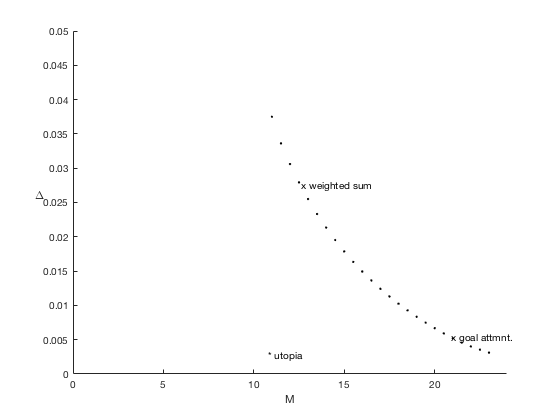

plot(M_p,Delta_p,'k.')
text(M_u,Delta_u,'* utopia')
text(f_ws(1),f_ws(2),'x weighted sum')
text(f_ga(1),f_ga(2),'x goal attmnt.')
axis([0 24 0 0.05])
box off, xlabel('M'),ylabel('\Delta','rot',0)

Alternatively, the Pareto front could be computed using the weighted sum method with various weights, or using the goal attainment method with various weights. 